# Lab - Systems of equations 2

**Topics: **Cholesky factorization, Gauss Seidel

## Cholesky factorization

clear, clc, format compact

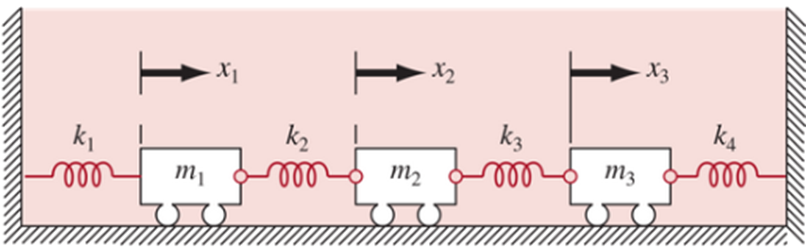

A 3 mass-4 spring system can be represented by:$\begin{array}{l}
\frac{k_1 +k_{2\;} }{m_{1\;} }x_1 -\frac{k_2 }{m_1 }x_2 =-\ddot{x_1 } \\
-\frac{k_2 }{m_2 }x_1 +\frac{k_2 +k_3 }{m_2 }x_2 -\frac{k_3 }{m_2 }x_3 =-\ddot{x_2 } \\
-\frac{k_3 }{m_3 }x_2 +\frac{k_3 +k_4 }{m_3 }x_3 =-\ddot{x_3 } 
\end{array}$s

If the accelerations of the three masses are 0.9, 0, and -0.1 m/s/s respectively, what are their displacements if all masses are 1 kg and k1=k4=10 N/m and k2=k3=40 N/m?

k1 = 10; % spring constant for spring 1 [N/m]
k2 = 40; % spring constant for spring 2 [N/m]
k3 = k2; % spring constant for spring 3 [N/m]
k4 = k1; % spring constant for spring 4 [N/m]

m = 1; % mass for all masses [kg]

A = [(k1+k2)/m -k2/m 0; 
    -k2/m (k2+k3)/m -k3/m;
     0 -k3/m (k3+k4)/m]

A =     50   -40     0
   -40    80   -40
     0   -40    50



b = [0.9; 0; -0.1]; % acceleration in m/s/s


### Is A positive & definite?

% all eigenvalues must be > 0
eig(A);
% if symmetric then subtracting the transpose
% from the original should give matrix of zeros
A-A';

### Create U


$$u_{\textrm{ii}} =\sqrt{a_{\textrm{ii}} -\sum_{k=1}^{i-1} u_{\textrm{ki}}^2 }$$
   
$$u_{\textrm{ij}} =\frac{a_{\textrm{ij}} -\sum_{k=1}^{i-1} u_{\textrm{ki}} u_{\textrm{kj}} }{u_{\textrm{ii}} }$$


U = zeros(3,3);
U(1,1) = sqrt(A(1,1));
U(1,2) = A(1,2)/U(1,1);
U(1,3) = A(1,3)/U(1,1);

U(2,2) = sqrt(A(2,2)-U(1,2)^2);
U(2,3) = (A(2,3)-U(1,2)*U(1,3))/U(2,2);

U(3,3) = sqrt(A(3,3)-(U(1,3)^2+U(2,3)^2))

U =     7.0711   -5.6569         0
         0    6.9282   -5.7735
         0         0    4.0825


**Checkpoint #1: **$U^T U=A$

(U'*U)-A

ans = 1.0e-14 *

    0.7105         0         0
         0         0         0
         0         0         0


### Find d

d = U'\b;

**Checkpoint #2: **$U^T d=b$

(U'*d)-b;

### Find x

x = U\d;

**Checkpoint #3: **$\textrm{Ax}=b$

(A*x)-b;

## Gauss-Seidel

clear, clc, format compact

This system of equation is designed to determine concentrations$\left(\textrm{in}\;\frac{g}{m^3 }\right)$in a series of coupled reactors as a function of the amount of mass input to each reactor in (g/day). Solve with the Gauss-Seidel method to $\varepsilon_s =5%$


$$\begin{array}{l}
15c_1 -3c_2 -c_3 =3800\\
-3c_1 +18c_2 -{6c}_3 =1200\\
-4c_1 -c_2 +12c_3 =2350
\end{array}$$


currErr = 100; % need to stop somewhere
iter = 0;
c = zeros(3,1) ; % Initial guess for x

% Method of calculating error
MPRAE = @(new_estimate, old_estimate) abs(new_estimate - old_estimate)./new_estimate * 100;

targetError = 5;

c1_calc = @(c2,c3) (3800+ 3*c2 +c3)/15;
c2_calc = @(c1,c3) (1200 + 3*c1 +6*c3)/18;
c3_calc = @(c1,c2) (2350 + 4*c1 + c2)/12;

while max(currErr) > targetError
    iter = iter +1;
    c_old = c;
    fprintf('itieration #%g\n', iter)
    c(1) = c1_calc(c(2),c(3));
    c(2) = c2_calc(c(1),c(3));
    c(3) = c3_calc(c(1),c(2))
    currErr = MPRAE(c,c_old);
   

end

itieration #1


c =   253.3333
  108.8889
  289.3519


itieration #2


c =   294.4012
  212.1842
  311.6491


itieration #3


c =   316.5468
  223.3075
  319.9579


itieration #4


c =   319.3254
  226.5402
  321.1535


### Results

fprintf('The solution is c_1 = %7.4f, c_2 = %7.4f, c_3 = %7.4f\n  after %d iterations, with an error of %3.2f%%, %3.2f%%, %3.2f%%\n',c(1), c(2),c(3), iter, currErr)

The solution is c_1 = 319.3254, c_2 = 226.5402, c_3 = 321.1535
  after 4 iterations, with an error of 0.87%, 1.43%, 0.37%
